# Laboratory 5


$$H_f =\frac{3\ldotp 5}{s\left(0\ldotp 5s+1\right)}$$


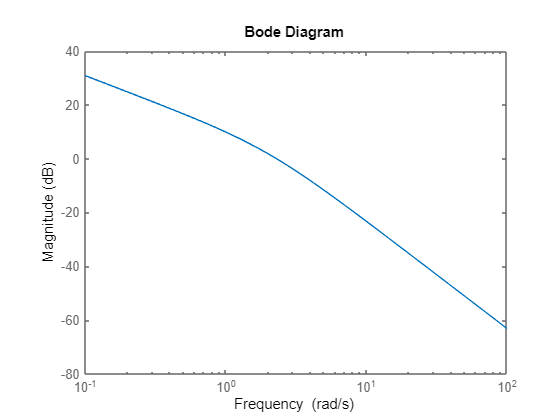

K = 3.5;
T = 0.5;
Hf = tf(K,[T 1 0]);
wco = 1/T;
wt = 2.3;
bodemag(Hf)

a)


$$\begin{array}{l}
\varepsilon_{\textrm{stp}}^* =0\\
\sigma^* \le 15%\\
t_s^* \le 15\left\lbrack \sec \right\rbrack \\
c_v^* \ge 1\\
\Delta w_n^* \le 15\left\lbrack \frac{\textrm{rad}}{\sec }\right\rbrack 
\end{array}$$


### P controller

sigmastar = 15/100;
sigma = sigmastar;
tsstar = 15;
cvstar = 20;
deltaWbstar = 2;
zeta = abs(log(sigma))/sqrt(pi^2+log(sigma)^2);
A = 1/4/zeta^2;
F = -14;
N = A;
Vr = 10^((N-F)/20);
Hd1 = Hf*Vr;
wn = 2*zeta*wt;
ts = 4/zeta/wn;
fprintf('ts = %.2f < 15',ts)

ts = 3.25 < 15

cv = 10^(9.9/20);
fprintf('cv = %.2f > 1',cv)

cv = 3.13 > 1

fprintf('deltawb = %.2f < 15',wt)

deltawb = 2.30 < 15

### PI controller

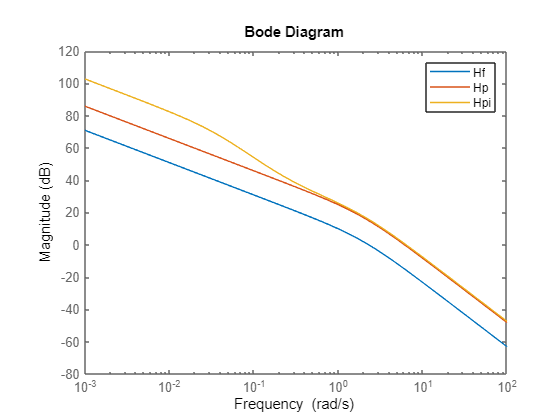

wz = 0.1*wt;
wp = cv/cvstar*wz;
Vrpi = 10^((cvstar-cv)/20);
Tz = 1/wz;
Tp = 1/wp;
Hpi = Vrpi*tf([Tz 1],[Tp 1]);
Hd2 = Hd1*Hpi;
close all
hold on
bodemag(Hf)
bodemag(Hd1)
bodemag(Hd2)
hold off
legend('Hf','Hp','Hpi')

b)


$$\begin{array}{l}
\varepsilon_{\textrm{stp}}^* =0\\
\sigma^* \le 15%\\
t_s^* \le 15\left\lbrack \sec \right\rbrack \\
c_v^* \ge 5\\
\Delta w_n^* \le 15\left\lbrack \frac{\textrm{rad}}{\sec }\right\rbrack 
\end{array}$$


### P controller

sigmastar = 15/100;
sigma = sigmastar;
tsstar = 15;
cvstar = 20;
deltaWbstar = 2;
zeta = abs(log(sigma))/sqrt(pi^2+log(sigma)^2);
A = 1/4/sqrt(2)/zeta^2;
F = -14;
N = A;
Vr = 10^((N-F)/20);
Hd1 = Hf*Vr;
wn = 2*zeta*wt;
ts = 4/zeta/wn;
fprintf('ts = %.2f < 15',ts)

ts = 3.25 < 15

cv = 10^(9.9/20);
fprintf('cv = %.2f > 5 false',cv)

cv = 3.13 > 5 false

fprintf('deltawb = %.2f < 15',wt)

deltawb = 2.30 < 15

### PI controller

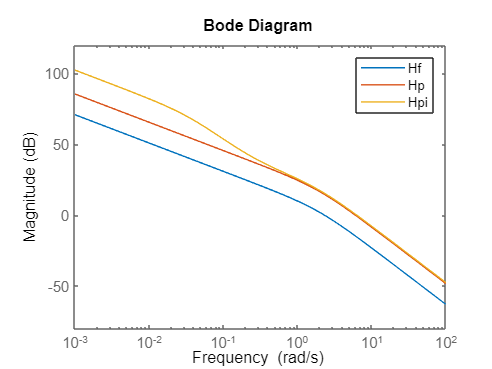

wz = 0.1*wt;
wp = cv/cvstar*wz;
Vrpi = 10^((cvstar-cv)/20);
Tz = 1/wz;
Tp = 1/wp;
Hpi = Vrpi*tf([Tz 1],[Tp 1]);
Hd2 = Hd1*Hpi;
close all
hold on
bodemag(Hf)
bodemag(Hd1)
bodemag(Hd2)
hold off
legend('Hf','Hp','Hpi')